## **Principles of Biosignals and Biomedical Imaging**

### **P3, 2nd Semester 2022/2023**

# **Vectors**

## **Lab Session 1**

### **Instituto Superior Técnico**

***100290, Armando Gonçalves***

***100357, Patrícia Marques***

# **1) Synthetic data**

**a) ***x = chirpTone(T, f1, f2, fs)**** definida no ficheiro chirpTone.m****.*

**b) **Listen the sound with f1 = 100, f2 = 2000 and fs = 4000 Hz.

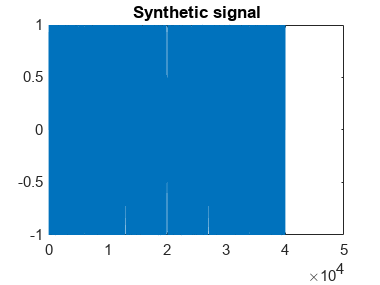

sData = chirpTone(10,100,2000,4000); %synthetic data
plot (sData);
title("Synthetic signal");

%soundsc(sData); %listen to it

**c) **Save the sound vector in an audio file to be read in normal audio players

fs = 4000; %sampling rate
audiowrite('synthetic.wav',sData,fs); %save in an audio file

# **2) Real data**

**a) Audio (1D)**

**i) **Read the audio file ”Let It Be.mp3”.

rData = audioread("Let It Be.mp3"); %real data

**b) **Compute the length of the file in seconds. Explain the approach you used. 

%informação acerca do ficheiro de áudio
audioinfo("Let It Be.mp3");
%retirar a sample rate
SRate = audioinfo("Let It Be.mp3").SampleRate;
%determinar o número de samples
SNumber = size(rData,1); % SNumber = audioinfo("Let It Be.mp3").TotalSamples
%a duração do ficheiro é igual ao número de samples sobre a sample rate
SLength = SNumber/SRate;

**c) **Reproduce the music backwards.

bData = flipud(rData); %flipped
%soundsc(bData);

**b) Electrocardiogram (1D)**

**i) **Read the *.mat file ”116m(2).mat”.

trace = load("116m(2).mat");

**ii) **Visualize the ECG trace and comment.

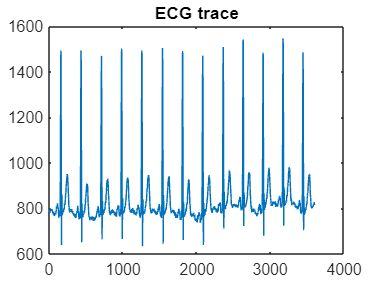

figure;plot(trace.val);
title("ECG trace");

- O ECG assemelha-se a um batimento cardíaco normal, distinguindo-se claramente os diferentes ciclos do coração (P wave, QRS complex e T wave).

**iii)** Estimate the sampling frequency that leads to a realistic ECG trace. 

%estimando que o sujeito está nos limites saudável de um adulto
fs=360;

**iv) **Detect the R peaks and estimate the heart rate (HR) from the inter-peak intervals. 

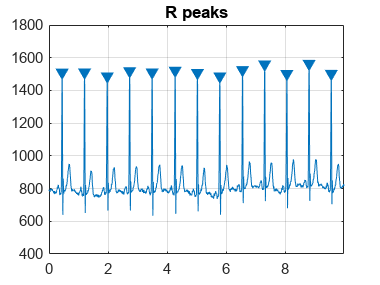

%extremos do sinal
findpeaks(trace.val,fs,'MinPeakHeight',1200); %visualize the peaks
title("R peaks");

[pks, locs] = findpeaks(trace.val,fs,'MinPeakHeight',1200) %indices

pks =         1492        1493        1469        1501        1493        1504        1490        1469        1508        1542        1484        1546        1485


locs =     0.4444    1.2056    1.9750    2.7333    3.4944    4.2750    5.0306    5.7889    6.5583    7.3083    8.0611    8.8139    9.5667


%heart rate estimation
time = diff(locs); %inter-peak intervals
hrAll = 60./time; %array with instantaneous hr
hr = mean(hrAll) %heart rate

hr = 78.9381

**b) Images (2D)**

**i) **Load the image "House8000.png" and creatively find hidden information in it.

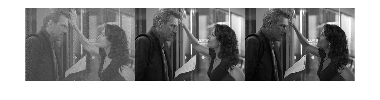

%read image
img = imread("House8000.png");
%representar os canais RGB isoladamente
montage([img(:,:,1),img(:,:,2),img(:,:,3)],'size',[1 NaN]);

%canal R aparenta ter ruído ou distorção
Rvector = double(reshape(img(:,:,1),[],1)); %vetorizar canal R
soundsc(Rvector) %ouvir o sinal do vetor R

**ii) ** Suggest and implement a method to improve the quality of that information.

%finding noise, we can later achieve a "cleaner" red channel
Restim = uint8(double(img(:,:,2))+double(img(:,:,3)))/2; %estimativa do canal vermelho, (G+B)/2
noise = img(:,:,1) - Restim; %noise, definido como canal vermelho menos a sua estimativa
imwrite(noise,"HouseNoise.png"); %save noise image
soundsc(reshape(double(noise),[],1),8000); %listen to noise as a vector

**iii) **Suggest and implement a method to recover the original image. Compute the Signal-to-noise ratio of the recovered image comparing it with the original one. **SNR**

clean = cat(3, Restim, img(:,:,2), img(:,:,3)); %recovered/clean image
imwrite(clean,"HouseClean.png"); %save clean image
original = imread("houseCuddy.jpg"); %read original image
SNR = snr(double(original(:,:,1)), double(Restim-original(:,:,1))) %compute the SNR, o 2º argumento é o ruido

SNR = 30.5291

%estávamos à espera que o sinal subisse mas não
%ocorre alias, f de amostragem de 4000 não é alta o suficiente para que
%isto aconteça